# Lab 4

Section 1 H = Vout/Vin

syms s R1 R2 C
Zc = 1/(s*C)

$$Zc = \frac{1}{C\,s}$$

Zs = simplifyFraction(R2 + Zc)

$$Zs = \frac{C\,R_{2}\,s+1}{C\,s}$$

H = simplifyFraction(Zs / (R1+Zs))

$$H = \frac{C\,R_{2}\,s+1}{C\,R_{1}\,s+C\,R_{2}\,s+1}$$

R1 = 4; R2 = 2; C = 3;
H = subs(H)

$$H = \frac{6\,s+1}{18\,s+1}$$

Section 2 Impulse and Step

% Convert symbolic equation to num and denom row vectors 
[symNum, symDen] = numden(H)

$$symNum = 6\,s+1$$

$$symDen = 18\,s+1$$

num = sym2poly(symNum)

num =      6     1


den = sym2poly(symDen)

den =     18     1



% Create a continuous-time model of the transfer function 
HTF = tf(num,den)


HTF =
 
  6 s + 1
  --------
  18 s + 1
 
Continuous-time transfer function.



% Check for stability using impulse
impulse(HTF)

% Check for stability using poles 
roots(den)

ans = -0.0556

pole(HTF)

ans = -0.0556

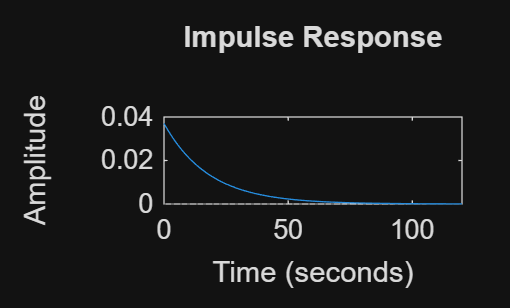

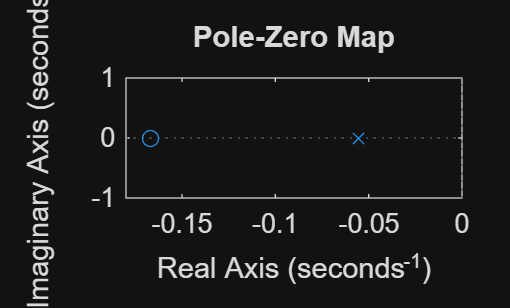

pzmap(HTF)


% Verify stability by checking whether all poles lie in the left half-plane
isStable = all(real(pole(HTF)) < 0)

isStable = logical
   1


Section 3 H = Vout/Vin

syms s R C2 L2
Zc = 1/(s*C2)

$$Zc = \frac{1}{C_{2}\,s}$$

Zl = s

$$Zl = s$$


Zs = simplifyFraction(R + Zc + Zl)

$$Zs = \frac{C_{2}\,s^{2}+C_{2}\,R\,s+1}{C_{2}\,s}$$

H = simplifyFraction(Zc / (Zs))

$$H = \frac{1}{C_{2}\,s^{2}+C_{2}\,R\,s+1}$$

Section 4

R=2

R = 2

C2 =9

C2 = 9

H= subs(H)

$$H = \frac{1}{9\,s^{2}+18\,s+1}$$


[symNum, symDen] = numden(H)

$$symNum = 1$$

$$symDen = 9\,s^{2}+18\,s+1$$

num = sym2poly(symNum);
den = sym2poly(symDen);
HTF = tf(num, den);

impulse(HTF)
poles = pole(HTF)

poles =    -1.9428
   -0.0572


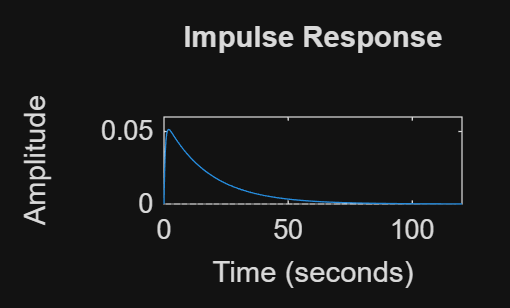

pzmap(HTF)

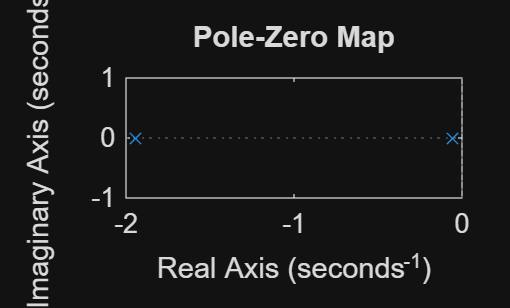

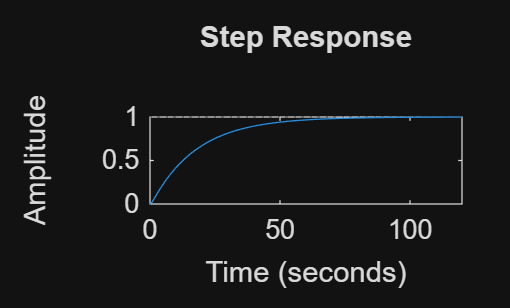


step(HTF)